clc; clear; close all;


## Load or Define Pressure-Time Data


load('E2038.mat');  % Load dataset
p_original = (p(:,3) - mean(p(1:100,3))) * 1000;  % Mean subtraction
Fs = fs;  % Sampling frequency in Hz
t = (0:length(p_original)-1)'/Fs;  % Time vector

%% Compute Original Parameters
E_original = sum(abs(p_original).^2);  % Total energy
Impulse_original = trapz(t, p_original);  % Impulse calculation
PeakPressure_original = max(abs(p_original));  % Peak pressure


## Define Cutoff Frequencies & Filter Orders to Test (Now Including Odd Orders)

### Perform Empirical Wavelet Transform (EWT)

MaxNumPeaks = 25; % Set max number of peaks for adaptive segmentation
[mra, cfs, wfb, info] = ewt(p_original, 'MaxNumPeaks', MaxNumPeaks);

#### Extract Peak Frequencies and Passbands

PeakFrequencies = Fs * info.PeakFrequencies;
freqPassbands = Fs * info.FilterBank.Passbands;
% cutoff_frequencies = linspace(100, 2000, 10);  % Test 10 different cutoff frequencies
cutoff_frequencies = PeakFrequencies;  % Test 10 different cutoff frequencies
filter_orders = [1, 2, 3, 4, 5, 6];  % Filter orders


## Matrices to store results


energy_ratio_matrix = zeros(length(filter_orders), length(cutoff_frequencies));
impulse_ratio_matrix = zeros(length(filter_orders), length(cutoff_frequencies));
peak_pressure_ratio_matrix = zeros(length(filter_orders), length(cutoff_frequencies));

%% Apply Low-Pass Filtering for Different Cutoff Frequencies & Orders
for f_idx = 1:length(filter_orders)
    for c_idx = 1:length(cutoff_frequencies)
        fc = cutoff_frequencies(c_idx);  % Current cutoff frequency
        filter_order = filter_orders(f_idx);  % Current filter order
        
        % Wn = fc / (Fs / 2);  % Normalize to Nyquist frequency
        % [b, a] = butter(filter_order, Wn, 'low');  % Butterworth low-pass filter
        % 
        % Apply filter
        % p_filtered = filtfilt(b, a, p_original);

        %         [z, p, k] = butter(filter_order, Wn, 'low');  % Zero-Pole-Gain format
        % sos = zp2sos(z, p, k);  % Convert to Second-Order Sections (stable)
        % p_filtered = filtfilt(sos, 1, p_original);  % Zero-phase filtering
        % if filter_order > 8
        %     warning('High filter order (%d) may be unstable. Try reducing it.', filter_order);
        % end
        % if size(sos, 2) ~= 6
        %     error('SOS matrix is not in correct format. Check filter design.');
        % end
        
        lpFilt = designfilt('lowpassiir', ...
            'FilterOrder', filter_order, ...
            'HalfPowerFrequency', fc, ...
            'SampleRate', Fs);
        % Zero-phase filtering
        p_filtered = filtfilt(lpFilt, p_original);
        % figure;
        % GD = grpdelay(lpFilt,10:1/Fs:1000,Fs)         % Plot group delay 
        % "n" Number of evaluation points, specified as a positive integer scalar no less than 2. When n is absent, it defaults to 512. For best results, set n to a value greater than the filter order.
        D = mean(grpdelay(lpFilt)) % Filter delay in samples
        % Compute energy, impulse, and peak pressure after filtering
        E_filtered = sum(abs(p_filtered).^2);
        Impulse_filtered = trapz(t, p_filtered);
        PeakPressure_filtered = max(abs(p_filtered));

        % Store results as ratio (%)
        energy_ratio_matrix(f_idx, c_idx) = (E_filtered / E_original) * 100;
        impulse_ratio_matrix(f_idx, c_idx) = (Impulse_filtered / Impulse_original) * 100;
        peak_pressure_ratio_matrix(f_idx, c_idx) = (PeakPressure_filtered / PeakPressure_original) * 100;
    end
end

D = 0.6619

D = 0.6634

D = 0.6828

D = 0.7415

D = 0.7871

D = 0.8407

D = 0.8807

D = 0.8898

D = 0.9645

D = 1.0729

D = 1.1491

D = 1.1984

D = 1.2596

D = 1.3019

D = 1.3734

D = 1.4870

D = 1.5448

D = 1.6281

D = 1.7699

D = 1.8593

D = 2.6417

D = 3.6380

D = 10.9704

D = 21.9179

D = 73.0367

D = 1.2190

D = 1.2198

D = 1.2265

D = 1.2366

D = 1.2560

D = 1.2944

D = 1.3312

D = 1.3402

D = 1.4221

D = 1.5552

D = 1.6543

D = 1.7198

D = 1.8021

D = 1.8595

D = 1.9575

D = 2.1144

D = 2.1950

D = 2.3110

D = 2.5083

D = 2.6341

D = 3.7497

D = 5.1642

D = 6.4271

D = 8.8197

D = 0.0489

D = 1.8777

D = 1.8785

D = 1.8697

D = 1.7984

D = 1.7912

D = 1.8290

D = 1.8761

D = 1.8883

D = 2.0020

D = 2.1913

D = 2.3324

D = 2.4257

D = 2.5430

D = 2.6248

D = 2.7637

D = 2.9869

D = 3.1009

D = 3.2657

D = 3.5471

D = 3.7246

D = 5.2876

D = 7.2999

D = 20.9527

D = 18.8083

D = 72.8688

D = 2.5820

D = 2.5827

D = 2.5433

D = 2.3537

D = 2.3276

D = 2.3758

D = 2.4392

D = 2.4556

D = 2.6075

D = 2.8579

D = 3.0437

D = 3.1665

D = 3.3202

D = 3.4271

D = 3.6098

D = 3.9019

D = 4.0509

D = 4.2665

D = 4.6341

D = 4.8648

D = 6.9195

D = 9.4173

D = 29.4149

D = 16.2963

D = 0.3558

D = 3.3182

D = 3.3186

D = 3.2276

D = 2.9012

D = 2.8667

D = 2.9313

D = 3.0126

D = 3.0334

D = 3.2247

D = 3.5368

D = 3.7676

D = 3.9198

D = 4.1104

D = 4.2432

D = 4.4696

D = 4.8313

D = 5.0161

D = 5.2818

D = 5.7389

D = 6.0258

D = 8.5619

D = 11.8222

D = 29.3347

D = Inf

D = 73.2000

D = 4.0783

D = 4.0780

D = 3.9123

D = 3.4458

D = 3.4100

D = 3.4926

D = 3.5920

D = 3.6172

D = 3.8475

D = 4.2214

D = 4.4976

D = 4.6791

D = 4.9071

D = 5.0661

D = 5.3356

D = 5.7673

D = 5.9879

D = 6.3063

D = 6.8501

D = 7.1911

D = 10.2354

D = 14.1108

D = 43.4320

D = Inf

D = 0.1153

## Plot Results: Separate 2D Plots for Each Filter Order

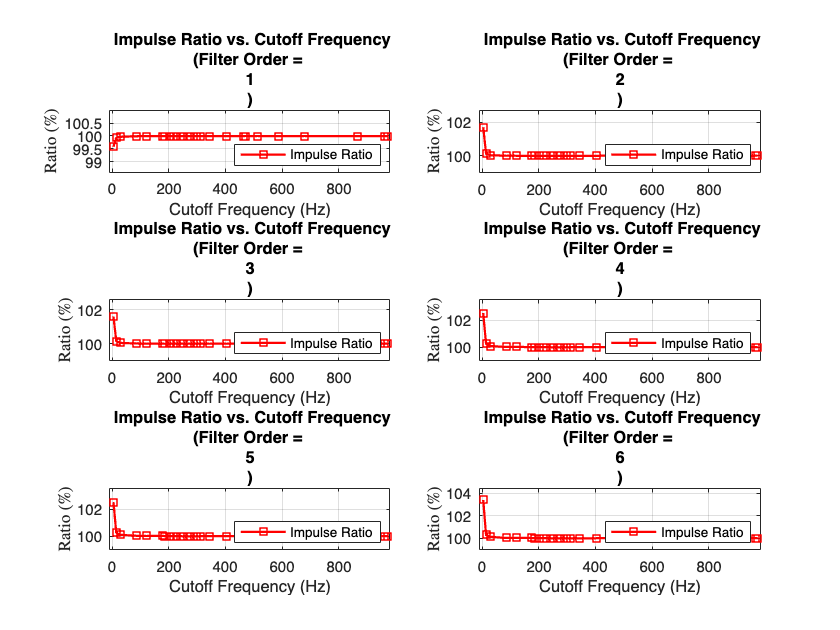

figure;

for f_idx = 1:length(filter_orders)
    subplot(3,2,f_idx);
    % plot(cutoff_frequencies, energy_ratio_matrix(f_idx, :), 'b-o', 'LineWidth', 1.5); hold on;
    plot(cutoff_frequencies, impulse_ratio_matrix(f_idx, :), 'r-s', 'LineWidth', 1.5);
    % plot(cutoff_frequencies, peak_pressure_ratio_matrix(f_idx, :), 'g-^', 'LineWidth', 1.5);
    hold off;
    
    xlabel('Cutoff Frequency (Hz)');
    xlim([-(max(cutoff_frequencies) * 0.01) max(cutoff_frequencies) + max(cutoff_frequencies) * 0.01 ])
    ylabel('Ratio (\%)',Interpreter='latex');
    ylim([(min(impulse_ratio_matrix(f_idx, :)) - min(impulse_ratio_matrix(f_idx, :)) * 0.01) max(impulse_ratio_matrix(f_idx, :)) + max(impulse_ratio_matrix(f_idx, :)) * 0.01 ])
    title({' Impulse Ratio vs. Cutoff Frequency','(Filter Order = ', num2str(filter_orders(f_idx)), ')'});
    legend('Impulse Ratio', 'Location','southeast');
    grid on;
end

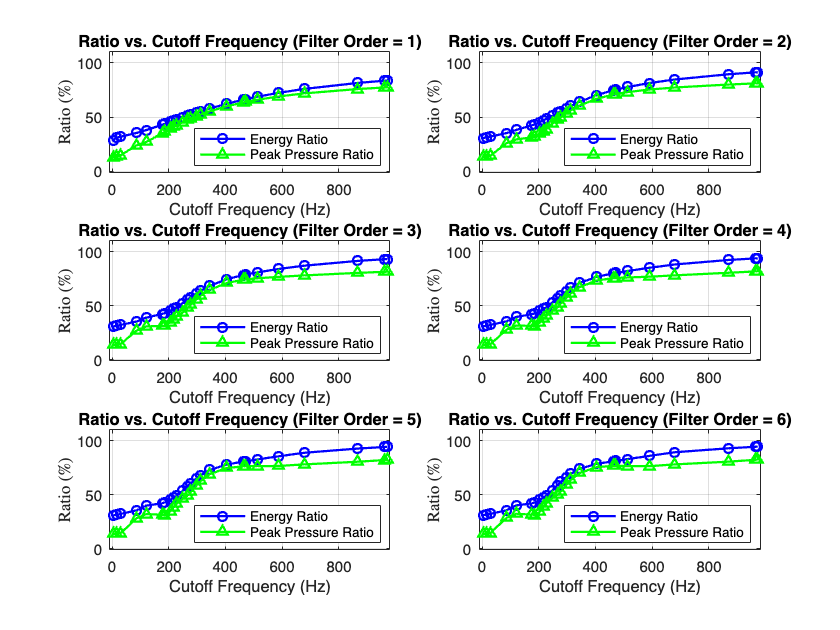


figure;

for f_idx = 1:length(filter_orders)
    subplot(3,2,f_idx);
    plot(cutoff_frequencies, energy_ratio_matrix(f_idx, :), 'b-o', 'LineWidth', 1.5); hold on;
    % plot(cutoff_frequencies, impulse_ratio_matrix(f_idx, :), 'r-s', 'LineWidth', 1.5);
    plot(cutoff_frequencies, peak_pressure_ratio_matrix(f_idx, :), 'g-^', 'LineWidth', 1.5);
    hold off;
    
    xlabel('Cutoff Frequency (Hz)');
    xlim([-(max(cutoff_frequencies) * 0.01) max(cutoff_frequencies) + max(cutoff_frequencies) * 0.01 ])
    ylabel('Ratio (\%)',Interpreter='latex');
    ylim([-1 110])
    title(['Ratio vs. Cutoff Frequency (Filter Order = ', num2str(filter_orders(f_idx)), ')']);
    legend('Energy Ratio', 'Peak Pressure Ratio','Location','southeast');
    grid on;
end